clc
clear all
%"Solution\distances from_gold_solution("n_data").txt"

n_data = 6;
str_sol = "Solution\distances from_gold_solution(";
str_my = "MY\distances from_gold(";
str = ").txt";
solutions_cell = cell(1, n_data + 1);
my_cell =  cell(1, n_data + 1);
for k = 0:n_data
  solutions_cell{k+1} = importdata(str_sol + num2str(k) + str);
  my_cell{k+1} = importdata(str_my + num2str(k) + str);
end


my_std_array = zeros(1, n_data);
my_mean_array = zeros(1,n_data);
sol_std_array = zeros (1, n_data);
sol_mean_array = zeros(1,n_data);
for k = 0:n_data
    my_std_array(k+ 1) = std(my_cell{k + 1});
    sol_std_array(k + 1) = std(solutions_cell{k + 1});
    my_mean_array(k + 1) = mean(my_cell{k + 1});
    sol_mean_array(k + 1) = mean(solutions_cell{k + 1});
end

my_MEAN = mean(my_mean_array);
my_MEAN = my_MEAN';
sol_MEAN = mean(sol_mean_array);
sol_MEAN = sol_MEAN';

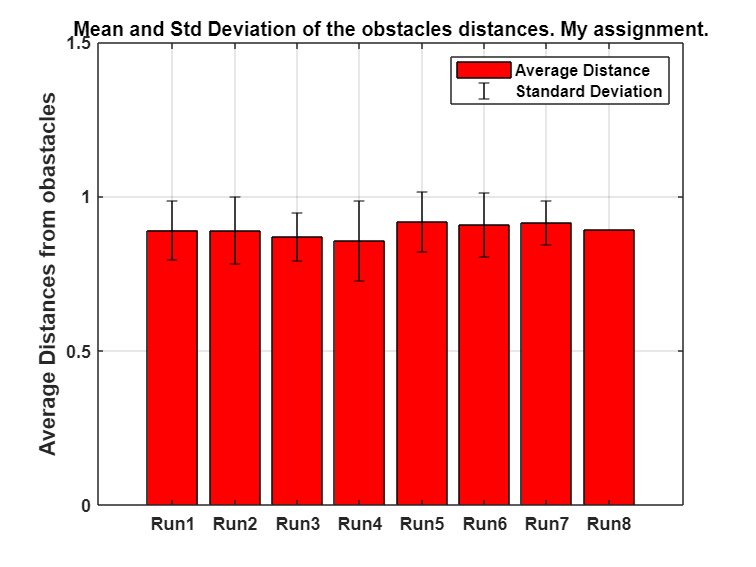

figure

y = [my_mean_array, my_MEAN];          
errY = [my_std_array, 0];              
h = barwitherr(errY, y);                    
title("Mean and Std Deviation of the obstacles distances. My assignment.")
set(gca,'XTickLabel',{'Run1','Run2','Run3', 'Run4', 'Run5', 'Run6', 'Run7', 'Run8', 'Total'},'fontweight','bold','fontsize',10);
legend('Average Distance', 'Standard Deviation');
ylabel('Average Distances from obastacles','fontweight','bold','fontsize',12);
ylim([0 1.5])
grid on
set(h(1),'FaceColor', 'r');

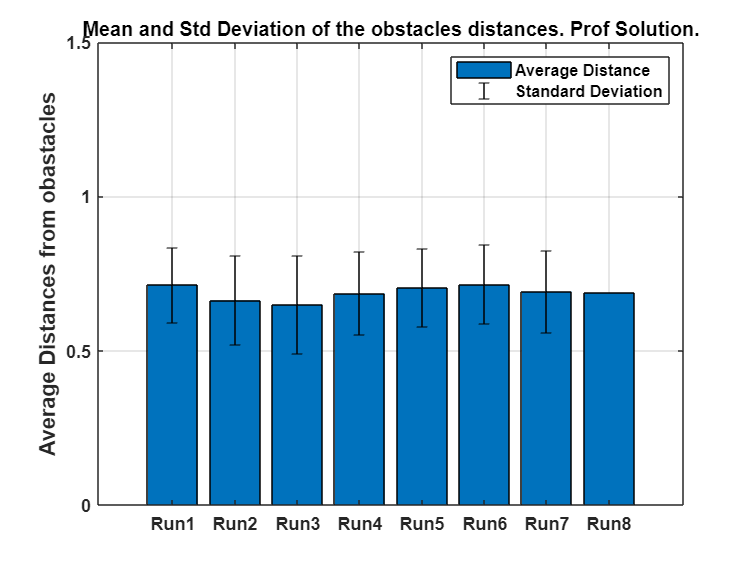

y2 = [sol_mean_array, sol_MEAN];             
errY2 = [sol_std_array, 0];         
h = barwitherr(errY2, y2);            
title("Mean and Std Deviation of the obstacles distances. Prof Solution.")
set(gca,'XTickLabel',{'Run1','Run2','Run3', 'Run4','Run5', 'Run6','Run7','Run8', 'Total'} ,'fontweight','bold','fontsize',10);
legend('Average Distance', 'Standard Deviation');
ylabel('Average Distances from obastacles','fontweight','bold','fontsize',12);
grid on
ylim([0 1.5])

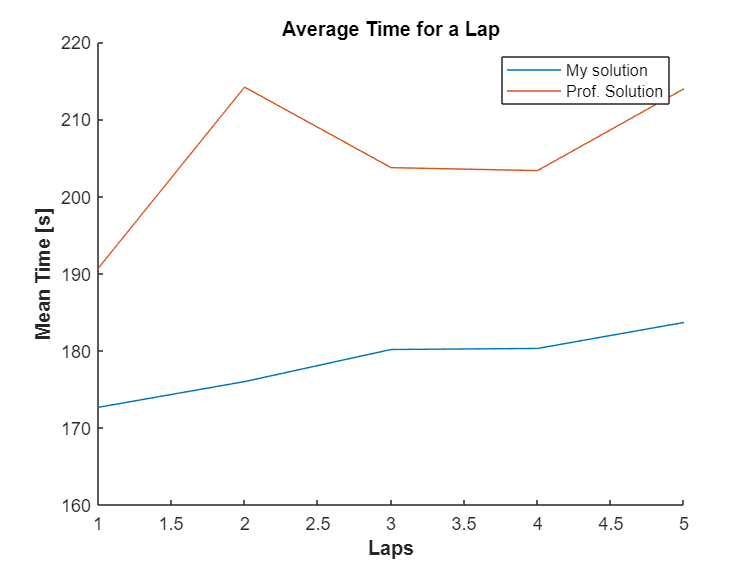

my_cell_data = cell(1, n_data + 1);
sol_cell_data = cell(1, n_data + 1);
my_str_time = "MY\time(";
sol_str_time = "Solution\time_solution(";
my_time_matrix = zeros(5, n_data); 
sol_time_matrix = zeros(5, n_data); 
for k = 0:n_data
  my_cell_data{k+ 1} = importdata(my_str_time + num2str(k) + str);
  my_time_matrix(:, k + 1) = my_cell_data{k+1}(: ,2);
  sol_cell_data{k+ 1} = importdata(sol_str_time + num2str(k) + str);
  sol_time_matrix(:, k + 1) = sol_cell_data{k+1}(: ,2);
end

my_mean_time = mean(my_time_matrix, 2);
sol_mean_time = mean(sol_time_matrix, 2);

figure
hold on 
plot(my_mean_time)
plot(sol_mean_time)
legend("My solution", "Prof. Solution")
ylabel("Mean Time [s]", FontWeight="bold")
xlabel("Laps", FontWeight="bold")
ylim([160 220])
title("Average Time for a Lap")

my_time_vector = my_time_matrix(:);
sol_time_vector = sol_time_matrix(:);
% H0: The mean time of the professor's solution is equal to the mean time of my
% solution. The alternative hypotesys Ha is that the professor's solution mean is grater than my solution mean. 
[h, p, ci, stats] = ttest2(sol_time_vector, my_time_vector, 'Tail', 'Right')

h = 1

p = 1.0772e-07

ci =    18.9353
       Inf


stats = struct with fields:
    tstat: 5.7678
       df: 68
       sd: 19.3191


% h = 1, Therefore ttest2 rejects the null hypothesis at the
% default 5% significance level. So, the professor's solution takes a greater amount of time in completing a lap with respect to my solution.  

my_dist_col = zeros(1, n_data);
my_dist_col = [my_cell{1}; my_cell{2}; my_cell{3}; my_cell{4}; my_cell{5}; my_cell{6}];
sol_dist_col = [solutions_cell{1}; solutions_cell{2}; solutions_cell{3}; solutions_cell{4}; solutions_cell{5}; solutions_cell{6}];
% H0: The mean distance from obstacles of the professor's solution is equal to the mean distance from obstacles of my solution. 
% The alternative hypotesys Ha is that my solution's mean is grater than professor's solution mean. 
[h, p, ci, stats] = ttest2(my_dist_col, sol_dist_col, 'Tail', 'right')

h = 1

p = 1.3896e-127

ci =     0.1993
       Inf


stats = struct with fields:
    tstat: 27.2415
       df: 1185
       sd: 0.1116


% h = 1, Therefore ttest2 rejects the null hypothesis at the
% default 5% significance level. So, the my solution robot keeps a grater
% distance from obstacles with respect to the professor robot. 
